# Noise Variances

% Run script

run('Noise_estimation.m');

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% Clear variables
clear;
clear global;
close all;
clc;

% Run trajectory
% q_trajectory frequency --> q1: pi/4(pi/4)
%                            q2: pi/3(pi/4)
%                            q3: pi/3(pi/4)
%                            q4: q0_model(4) + pi/9(pi/4)
%                            q5: pi/10(0.8*pi)
%                            q6: pi/10(0.8*pi)
%                            q7: pi/10(0.8*pi)
% q_trajectory_2 frequency --> q1: pi/4(pi)
%                              q2: pi/3(1.5*pi)
%                              q3: pi/3(1.2*pi)
%                              q4: q0_model(4) + pi/9(pi)
%                              q5: pi/10(0.8*pi)
%                              q6: pi/10(0.8*pi)
%                              q7: pi/10(0.8*pi)
% q_trajectory_3 frequency --> q1: -pi/7(0.2*pi) + pi/8(0.5*pi) + pi/6(1.5*pi) 
%                              q2: pi/8(0.4*pi) - pi/8(1.4*pi) + pi/8(pi) 
%                              q3: pi/6(0.3*pi) - pi/10(1.7*pi) 
%                              q4: pi/6 + pi/9(pi) - pi/7(1.2*pi)
%                              q5: pi/10(0.8*pi)
%                              q6: pi/10(0.8*pi)
%                              q7: pi/10(0.8*pi)

% load('q_trajectory.mat');
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;

% Run human_arm_parameters
run('human_arm_parameters.m');

% Markers
arm.markers.radius = 0.01; % [m]

% Name directory
directory = strcat('S', num2str(shoulder_num), '_F', num2str(forearm_num), '_H', num2str(hand_num));
% Run script
mex_generation(arm.markers.links, sample_Time, 'false');

% See if any singularities are present
max_number_simulations = 100;
singular_config(q_traj, shoulder_num, forearm_num, hand_num, 1e-10, max_number_simulations);

   8.2510e-05



num_simulations_tot = 1

Set of SHOULDER markers:0.056536
Set of SHOULDER markers:  -0.039
Set of SHOULDER markers:0.020091
Set of FOREARM markers:-0.013264    0.013278
Set of FOREARM markers: -0.12918    -0.16555
Set of FOREARM markers: 0.037737    0.037732
Set of HAND markers:0.029849    0.048749
Set of HAND markers:-0.15137    -0.13736
Set of HAND markers:    0.03        0.03


# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;

% Human arm parameters
run('human_arm_parameters.m');

## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = q_traj.signals.values(1, :)';

% LS IC
q0_LS = q0_model;

% Results
LS_KF_EKF_NLDM("LS", 'precomputed', [], directory);

## 2.  WRONG GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = q_traj.signals.values(1, :)';

% LS IC
q0_LS = zeros(n, 1);

% Results
LS_KF_EKF_NLDM("LS", 'precomputed', [], directory);

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{\tilde{u}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{\tilde{u}}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{\tilde{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{\tilde{u}}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_traj.signals.values(1, :)';

% Sample time is fixed at 0.01
LS_KF_EKF_NLDM("NLDM", 'precomputed', [], directory);

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta \tilde{u}}_{k} = \mathbf{\tilde{u}}_k - \mathbf{u}_{eq} \\
\mathbf{\tilde{u}}_k = \mathbf{\bar{u}}_k + \mathbf{n}_k
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


In simulink, the above state space representaion was implemented. Th considered input was  $\mathbf{\Delta \tilde{u}}_k + \mathbf{n}_k$, so that $\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot (\mathbf{\Delta \tilde{u}}_k  + \mathbf{n}_k)$,            $\mathbf{n}_k \sim \mathcal{N}(0, \mathbf{N})$

The matrix $\mathbf{N}$ was computed such that $\mathbf{GNG^T} = \mathbf{Q}$

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_traj.signals.values(1, :)';

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 0.1 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'precomputed', number_samples, directory);

### 3.2 Free arm motion

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°.


$$q_0 = \pmatrix{0\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{0 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The comparison between simulation and linearized discrete state-space is reported below.

% Model IC
q0_model = zeros(n, 1);

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', number_samples, directory);

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;
  
% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_traj.signals.values(1, :)' + [0.5*rand(4, 1); 0.4*rand(3,1)];

% Initial estimate q0
ekf.q0 = q0_model;

% Initial covariance estimate P0
ekf.P0 = diag([0.5;0.5;0.5;100;10;1;10]);

% Results
LS_KF_EKF_NLDM("EKF", 'precomputed', number_samples, directory);

# Comparison between Methods

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory_3.mat');
q_traj = q_trajectory_3;

% Human arm parameters
run('human_arm_parameters.m');
                                                                                                                                                                                                                                                                                                
% Model IC 
q0_model = q_traj.signals.values(1, :)' + [0.5*rand(3, 1); 0.3*rand(4,1)];
%q0_model = [0.6035;0.9644;0.4325;1.2184;0.3032;0.1731;0.2622];
q0_model*180/pi

## LS

% LS IC
q0_LS = q0_model;

## KF

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = diag([0.1;0.1;0.1;8;0.1;1;1]);

## EKF

% Initial estimate q0
ekf.q0 = q0_model;

% Initial covariance estimate P0
ekf.P0 = diag([0.5;0.5;0.5;100;10;1;10]);

## Results

LS_KF_EKF_NLDM(["EKF"], 'precomputed', number_samples, directory);

# Experimental simulations

One simulation is run in order to estimate $t_{Sh}^{0, 0Conf}$ (the position of the shoulder wrt Super marker 0 when ARM IS AT 0 CONFIGURATION) necessary for the mex functions generation. This first estimate is then used to compute $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$(the position of the markers wrt corresponding Bases RF).

## Position of the shoulder wrt Super marker 0 when ARM IS AT 0 CONFIGURATION

run('parameters_tuning.m');

Only f_Phi and f_J are generated with $t_{Sh}^{0, 0Conf}$ since only these functions are needed to compute the position and velocity of the markers wrt corresponding Bases RF.

## Mex functions generation

% Clear variables
clear;
clear global;
close all;  
clc;

% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run human_arm_parameters
run('human_arm_parameters.m');

% tSh_0, 0 Configuration
tSh_0_0Conf = [0.01; -0.229; -0.261];

% Generate mex files
mex_generation_Experiments(arm.markers.links, sample_Time, tSh_0_0Conf, 'true', 'true');

$t_{Sh}^{0, 0Conf}$is used to compute $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$ when arm is at 0 configuration and these estimates are then used to compare the position measurement of the markers and FK function evaluated at q = 0.

% Clear variables
clear;
clear global;
close all;  
clc;
% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run model_validation
run('model_validation.m');

Now that the model is validated,  $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$ will be used in the following (markers' positions are constant wrt Bases RF of each link). However, new mex functions will be generated using a different position of the Shoulder wrt Super marker 0, $t_{Sh}^{0, Robust}$ which is an average of different Shoulder positions since it slightly moves when the arm moves.

## Position of the shoulder wrt Super marker 0 when ARM IS MOVING

run('parameters_tuning.m');

Mex functions are generated with $t_{Sh}^{0, Robust}$.

## Mex functions generation

% Add path of the Experiments folder
addpath('Functions/Experiments/');

% Run human_arm_parameters
run('human_arm_parameters.m');

% tSh_0, Robust
tSh_0_Robust = [0.03; -0.246; -0.32];

% Generate mex files
mex_generation_Experiments(arm.markers.links, sample_Time, tSh_0_Robust, 'false', 'true');

## Noise estimation Rp, Rv ---> R = Rp,  Qk = Gk*Rv*Gk' (K < N) (N is a parameter)

R is the covariance matrix of the markers' position noise.

run('R_estimation.m'); 

The value of the ROS_IP environment variable, 12.0.10.191, will be used to set the advertised address for the ROS node.


The value of the ROS_IP environment variable, 12.0.10.191, will be used to set the advertised address for the ROS node.


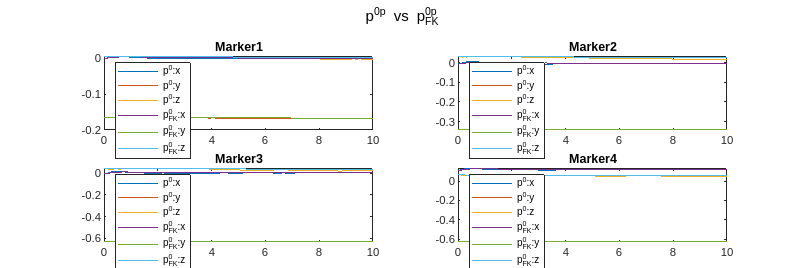

% Add path of the Experiments folder
addpath('Scripts/');
addpath('Functions/');
addpath('Scripts/Experiments/');
addpath('Functions/Experiments/');
% Run model_validation
run('model_validation.m');

## Experimental results

Use Model validation to compute  $m_{Shoulder}^{RF_{Sh}},  \ m_{Forearm}^{RF_{El}}, \ m_{Hand}^{RF_{Wr}}$.

After, the function is run to compute the estimates.

% Run Human arm aparameters
run('human_arm_parameters_exp.m')

% Load Noise and Markers
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_shoulder.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_forearm.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_6/markers_hand.mat'));
load(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/noise.mat'));

## LS

%%%
%%% LS Initial estimate
%%%
q0_LS = zeros(7, 1);

## EKF

%%%
%%% EKF Initial estimate q0
%%%
ekf.q0 = zeros(7, 1);

%%%
%%% EKF Initial Covariance P0
%%%
ekf.P0 = diag(ones(7, 1));

## Choose method

The value of the ROS_IP environment variable, 12.0.10.191, will be used to set the advertised address for the ROS node.


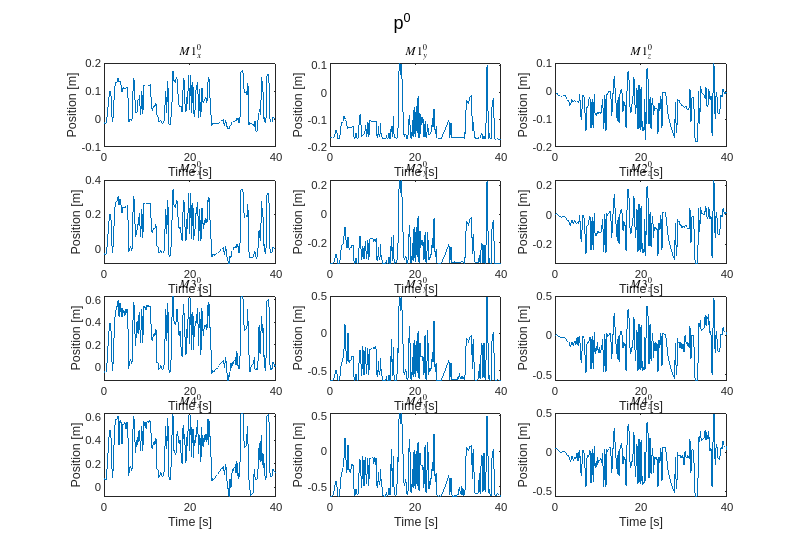

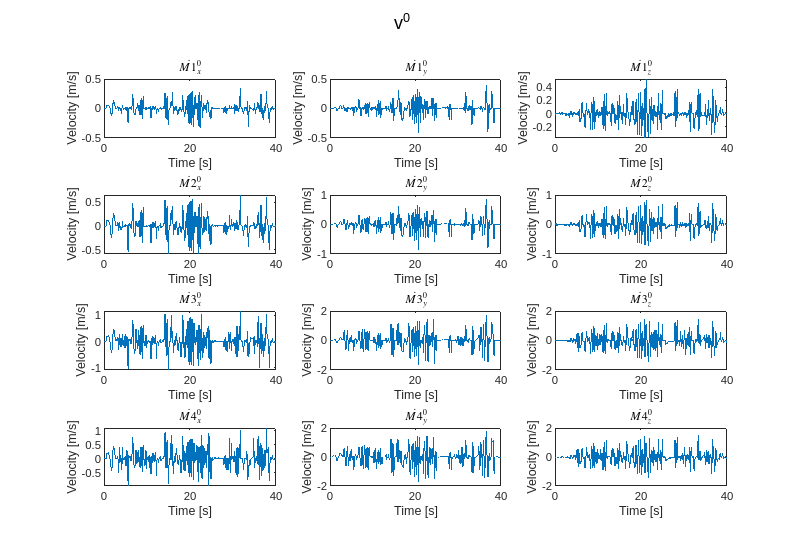

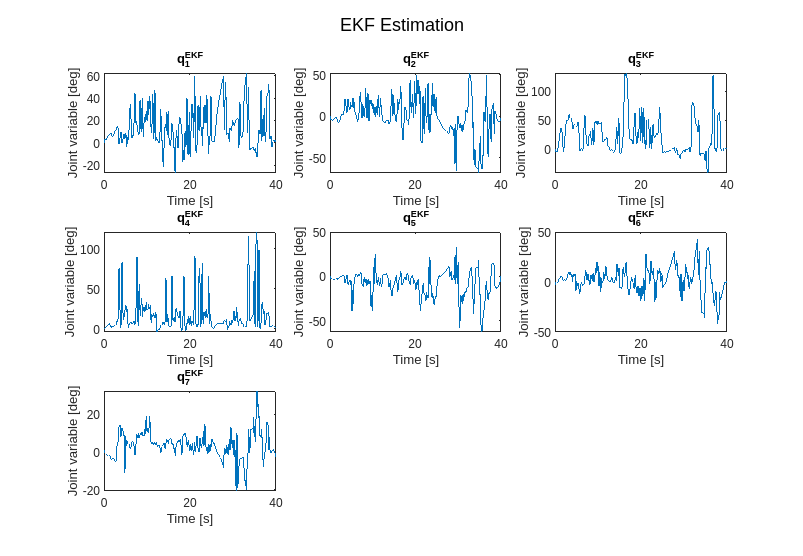

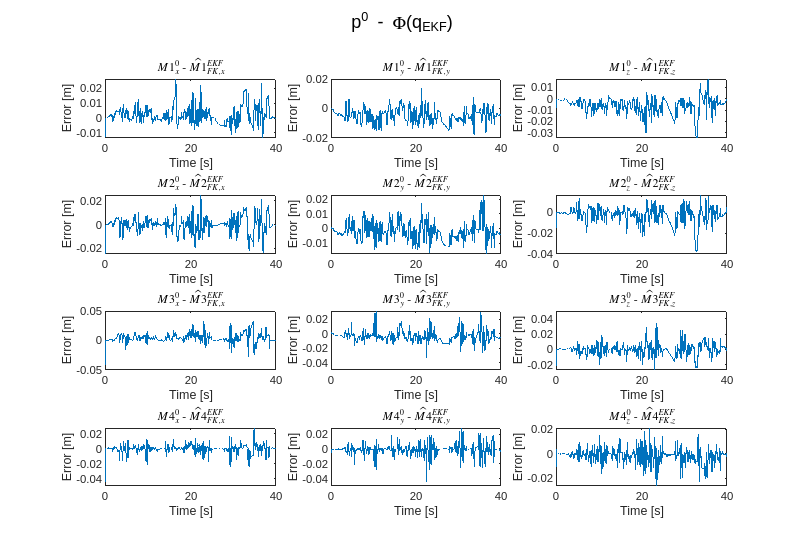

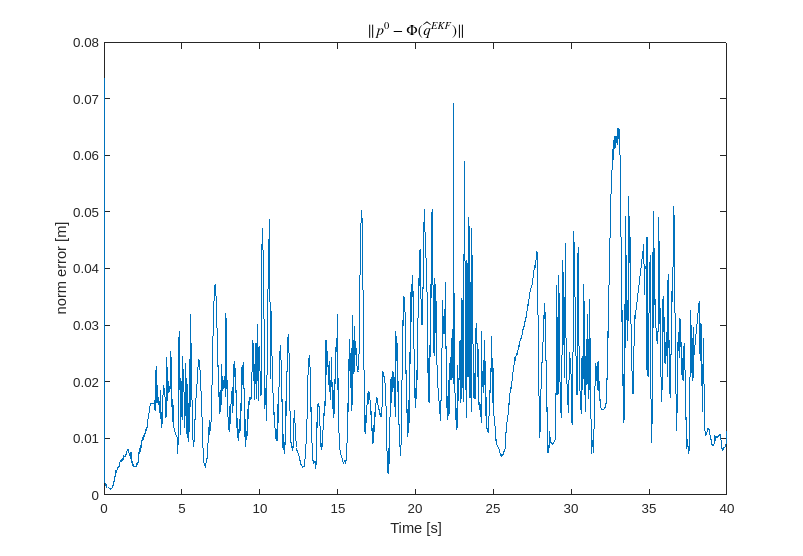

% Run function

%%%
%%% Simulation time
%%%
simulink.time = 40;

%%%
%%% Choose method
%%%
method_flag = "EKF";
out = LS_KF_EKF_exp(method_flag, directory);

% Save variables
p_0p = out.p_0p;
v_0p = out.v_0p;
marker_case = 6; 
sim_num = 1;
save(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_', num2str(marker_case), '/Sim_', num2str(sim_num), '/p_0p.mat'), 'p_0p');
save(strcat('/home/gioel/Documents/Master_thesis/Human arm/Simulations/', directory, '/Markers_Pos_', num2str(marker_case), '/Sim_', num2str(sim_num), '/v_0p.mat'), 'v_0p');
clear marker_case sim_num p_0p v_0p;

% Run Human arm aparameters
run('human_arm_parameters_exp.m');

ekf.P0 = diag(ones(7, 1));


simulink.time = 10;
set_param('master_thesis_simulink', 'StopTime', 'simulink.time');
%sim('master_thesis_simulink.slx');

remove_blocks_simulink_Experiments(shoulder_num, forearm_num, hand_num);

ekf.q0 = zeros(7, 1);
ekf.P0 = diag([1;1;1;1;1;1;1]);
noise.Q = diag([0.1 0.1 0.1 0.1 0.01 0.01 0.01]);
noise.R = noise.Rp * 9000;

%% Clear variables
clear;
clear global;
close all;  
clc;

%% Add path of the Used folder
addpath('Scripts/');
addpath('Functions/');
addpath('Scripts/Experiments/');
addpath('Functions/Experiments/');

%% Run Human arm aparameters
run('human_arm_parameters_exp.m');

## Least Squares (LS)

%%%
%%% LS IC
%%%
ls.q0 = deg2rad(0 * ones(n, 1));
%ls.q0 = deg2rad([10 0 5 -3 4 0 1]');

## Kalman Filter (KF)

%%%
%%% EKF IC
%%%
kf.Delta_q0 = 0 * ones(n, 1);

%%%
%%% KF equilibrium point {q_eq, v_0p_eq}
%%%
kf.q_eq = 0 * ones(n, 1);
kf.v_0p_eq = 0 * ones(3*m, 1);

%%%
%%% KF Initial Covariance 
%%%
kf.P0 = diag(ones(n, 1));

%%%
%%% KF Measurement Noise --> DEFAULT: noise.Rp * 9000
%%%
kf.R = [];

%%%
%%% KF Process Noise --> DEFAULT: diag([0.1 0.1 0.1 0.1 0.01 0.01 0.01])
%%%
kf.Q = [];

## Extended Kalman Filter (EKF)

%%%
%%% EKF IC
%%%
ekf.q0 = 0 * ones(n, 1);
%ekf.q0 = deg2rad([10 0 5 -3 4 0 1]');

%%%
%%% EKF Initial Covariance 
%%%
ekf.P0 = diag(ones(n, 1));

%%%
%%% EKF Measurement Noise --> DEFAULT: noise.Rp * 9000
%%%
ekf.R = [];

%%%
%%% EKF Process Noise --> DEFAULT: diag([0.1 0.1 0.1 0.1 0.01 0.01 0.01])
%%%
ekf.Q = [];

## Show Results

Set of markers: SHOULDER: 1, FOREARM: 1, HAND: 2
Markers SHOULDER: -0.0031
                 -0.1539
                 0.0013
Markers FOREARM: -0.0159
                -0.1131
                 0.0267
Markers HAND: -0.0265  0.0883
              -0.1078 -0.0996
               0.0267  0.0596
Sim n. 1


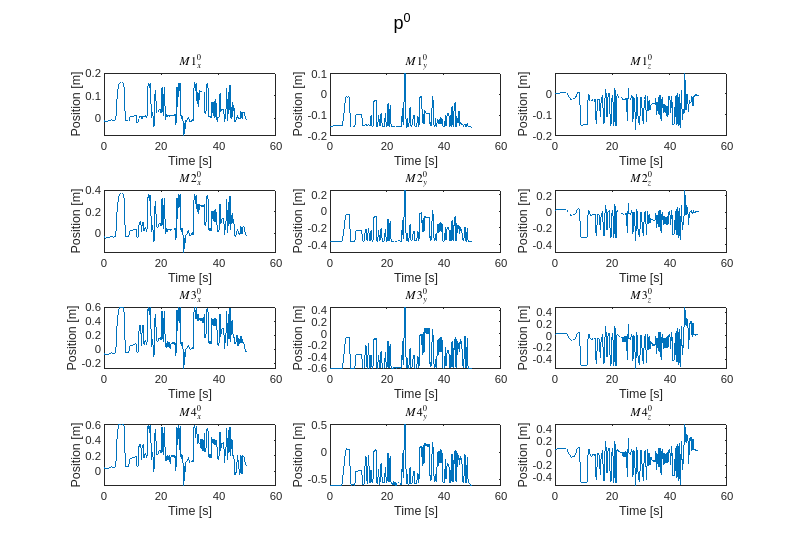

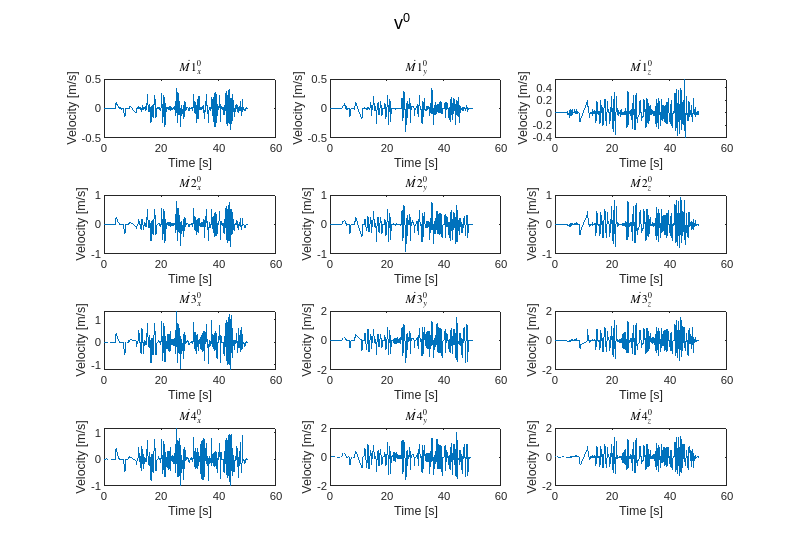

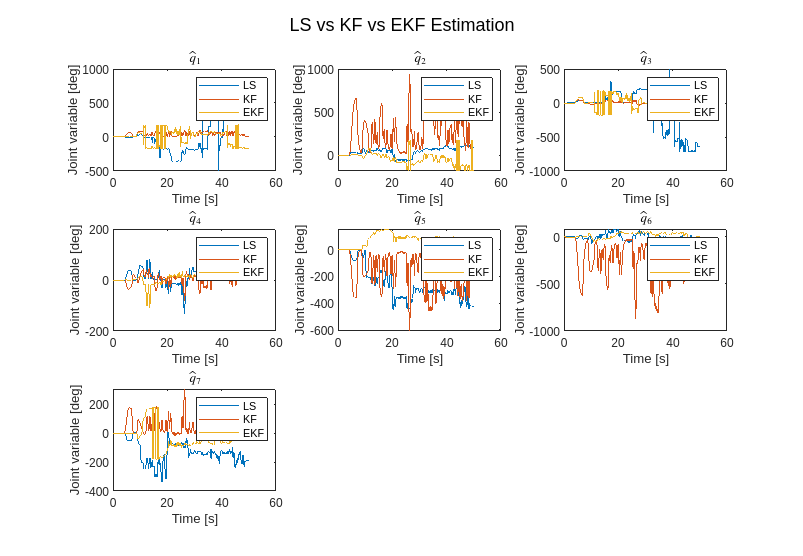

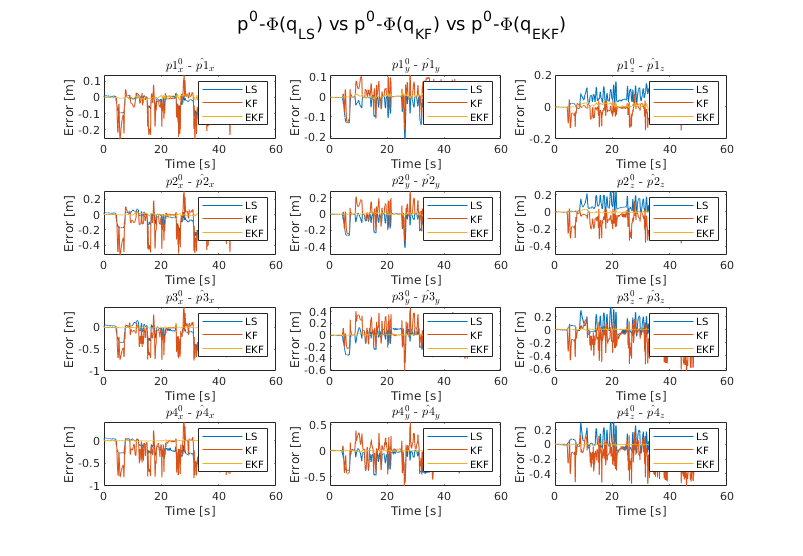

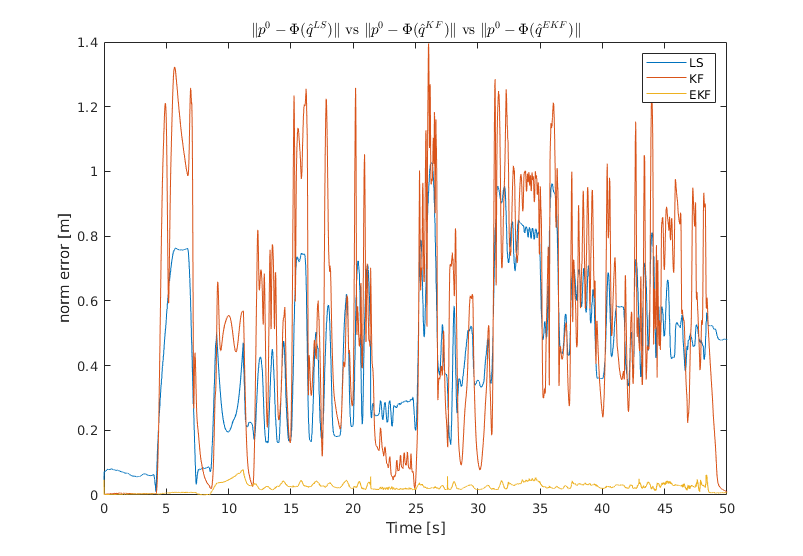

%%%
%%% Markers choice
%%%
markers_num = 4;

%%%
%%% Num Simulation 
%%%
sim_num = 1;

% Run function
%show_Results(ls.q0, ekf.q0, ekf.P0, ekf.R, ekf.Q, directory, markers_num, sim_num);
show_Results(directory, markers_num, sim_num);